# FM_main

clear; clc;

% 参数设置
T = 3;
A = 1;
dt = 0.001;
fs = 1/dt;
fc = 20;
fm = 4;
K_f = 20;

t = 0:dt:T-dt; % 时间向量
m_t = cos(2*pi*fm*t); % 单音调制信号

m_f = (K_f * A) / (2*pi*fm);
B = 2 * (m_f + 1) * fm;
disp(['调频指数是：', num2str(m_f)]);

调频指数是：0.79577


disp(['带宽是：', num2str(B)]);

带宽是：14.3662


## 调制

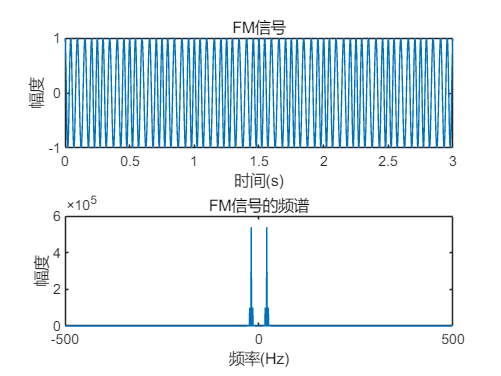

FM = FM_modulation(t,m_t,K_f,fc,A); % WBFM
[freq1,spectrum1] = analyze_spectrum(FM,fs,1000);
figure(2);
subplot(2,1,1);plot(t, FM);
title('FM信号');
xlabel('时间(s)');
ylabel('幅度');
subplot(2,1,2);plot(freq1, spectrum1);
title('FM信号的频谱');
xlabel('频率(Hz)');
ylabel('幅度');

## 通过信道

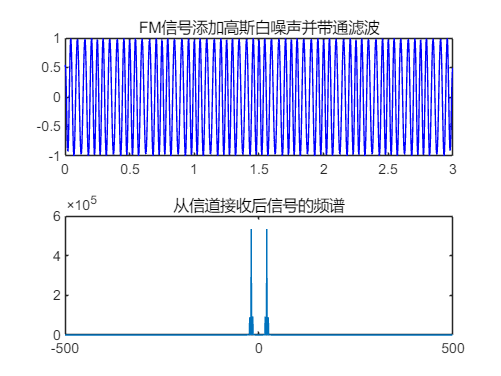

receive_signal = channel_simulation(FM, 40, fs, m_f, fm, fc);
[freq2,spectrum2] = analyze_spectrum(receive_signal,fs,1000);
figure(3);
subplot(2,1,1);plot(t,receive_signal, 'b');title('FM信号添加高斯白噪声并带通滤波');
subplot(2,1,2);plot(freq2,spectrum2);title('从信道接收后信号的频谱');

## 非相干解调

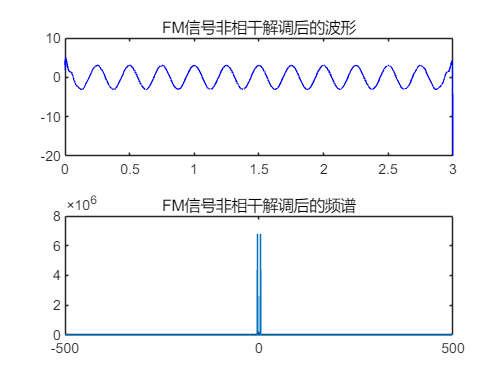

[analytic_signal, instantaneous_phase, instantaneous_frequency, output_signal] = FM_noncoherent_demodulation(receive_signal, fs, fc);
[freq3,spectrum3] = analyze_spectrum(output_signal,fs,1000);
figure(4);
subplot(2,1,1);plot(t,output_signal, 'b');title('FM信号非相干解调后的波形');
subplot(2,1,2);plot(freq3,spectrum3);title('FM信号非相干解调后的频谱');

## 中间过程，调试使用

figure(5);
subplot(3,1,1);plot(t,analytic_signal, 'b');

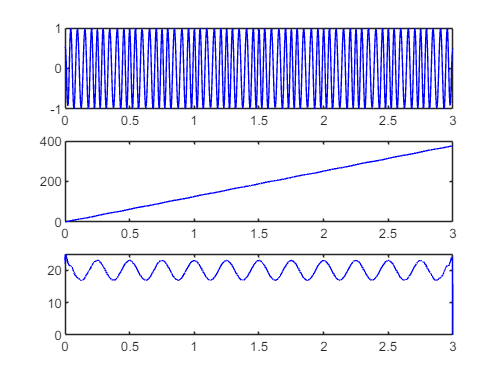

subplot(3,1,2);plot(t,instantaneous_phase, 'b');
subplot(3,1,3);plot(t,instantaneous_frequency, 'b');